## Part 1

Initialization

clear; clc; close all;

fft_size = 64;
cp_size = 16;
fs = 2e7;
subcarrier_spacing = fs / fft_size / 1e6;

idx_offset = 32;
null_carriers = [-31:-27 0 27:32];
pilot_tone_idx = [-21, -7, 7, 21];
pilot_tone_bits = randi([0 1], 4, 1) * 2 - 1; % Generate random bits and modulate with BPSK
data_tone_bits = randi([0 15], fft_size - length(pilot_tone_idx) - length(null_carriers), 1); % Generate random bits for 16-QAM
data_tone_modulated = qammod(data_tone_bits, 16, 'UnitAveragePower', true);
ofdm_symbol = zeros(fft_size, 1); % Initialize OFDM symbol with zeros
ofdm_symbol(pilot_tone_idx + idx_offset) = pilot_tone_bits; % Assign pilot tones
data_indices = setdiff(1:fft_size, [null_carriers + idx_offset, pilot_tone_idx + idx_offset]); % Find indices for data tones
ofdm_symbol(data_indices) = data_tone_modulated; % Allocate modulated data tones to remaining indices

(1) Plot the magnitude of the frequenycy spectrum for the OFDM symbol

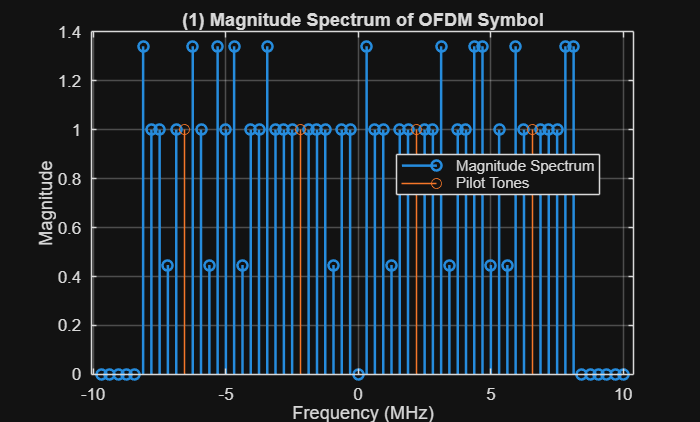

figure;
% Compute the frequency axis for plotting
f = subcarrier_spacing * (-31:32);

% Plot the magnitude of the FFT without the pilot tones
ofdm_symbol_without_pilots = ofdm_symbol; % Copy the OFDM symbol
ofdm_symbol_without_pilots(pilot_tone_idx + idx_offset) = []; % Remove pilot tones completely
f_without_pilots = f;
f_without_pilots(pilot_tone_idx + idx_offset) = [];
stem(f_without_pilots, abs(ofdm_symbol_without_pilots), 'LineWidth', 1.5); hold on;

% Highlight the pilot tones
stem(f(pilot_tone_idx + idx_offset), abs(ofdm_symbol(pilot_tone_idx + idx_offset)), 'DisplayName', 'Pilot Tones');

% Label the axes
xlabel('Frequency (MHz)');
ylabel('Magnitude');
title('(1) Magnitude Spectrum of OFDM Symbol');
grid on;

% Add legend
legend('Magnitude Spectrum', 'Pilot Tones', 'Location', 'Best');
hold off;

(2) Adjacent subcarrier spacing?

disp(['(2) ' num2str(subcarrier_spacing) ' MHz']);

(2) 0.3125 MHz


(3) Time domain OFDM signal

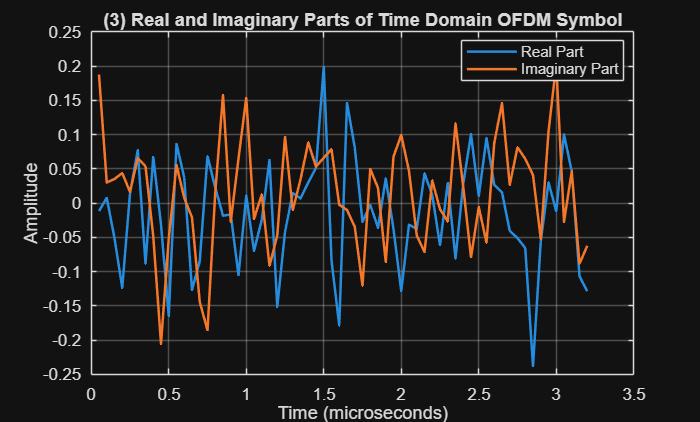

ofdm_symbol_ifft = ifft(ifftshift(ofdm_symbol));

% Plot the real and imaginary parts of the time domain OFDM symbol
sampled_time = (1 / fs * 1e6) * (1:length(ofdm_symbol_ifft));
figure;
plot(sampled_time, real(ofdm_symbol_ifft), 'LineWidth', 1.5); 
hold on;
plot(sampled_time, imag(ofdm_symbol_ifft), 'LineWidth', 1.5);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('(3) Real and Imaginary Parts of Time Domain OFDM Symbol');
legend('Real Part', 'Imaginary Part', 'Location', 'Best');
grid on;
hold off;

(4) Add CP 

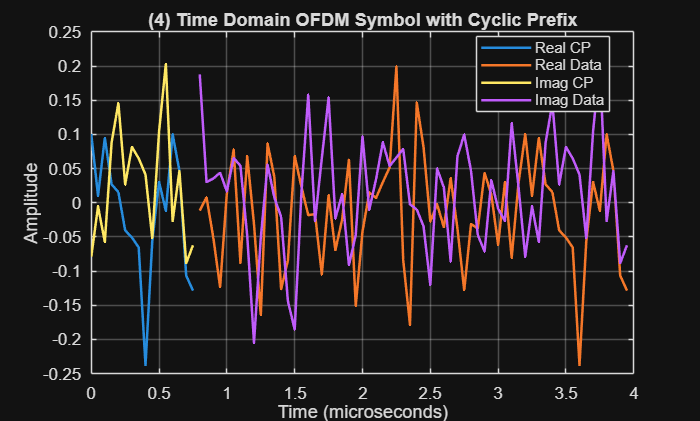

% Add cyclic prefix to the time domain OFDM symbol
cyclic_prefix = ofdm_symbol_ifft(end-cp_size+1:end); % Extract the last cp_size samples for cyclic prefix
ofdm_with_cp = [cyclic_prefix; ofdm_symbol_ifft]; % Prepend cyclic prefix to the OFDM symbol

% Plot the time domain signal with cyclic prefix
sampled_time_with_cp = (1 / fs * 1e6) * (0:length(ofdm_with_cp)-1); % Adjust time vector for the new signal
figure;
plot(sampled_time_with_cp(1:cp_size), real(ofdm_with_cp(1:cp_size)), 'LineWidth', 1.5); 
hold on;
plot(sampled_time_with_cp(cp_size+1:end), real(ofdm_with_cp(cp_size+1:end)), 'LineWidth', 1.5);
plot(sampled_time_with_cp(1:cp_size), imag(ofdm_with_cp(1:cp_size)), 'LineWidth', 1.5);
plot(sampled_time_with_cp(cp_size+1:end), imag(ofdm_with_cp(cp_size+1:end)), 'LineWidth', 1.5);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('(4) Time Domain OFDM Symbol with Cyclic Prefix');
legend('Real CP', 'Real Data', 'Imag CP', 'Imag Data', 'Location', 'Best');
grid on;
hold off;

(5) Duration with cyclic prefix? Without cyclic prefix?

disp(['(5-1) Without cyclic prefix: ' num2str(sampled_time(end)) ' microseconds']);

(5-1) Without cyclic prefix: 3.2 microseconds


disp(['(5-2) With cyclic prefix: ' num2str(sampled_time_with_cp(end)) ' microseconds']);

(5-2) With cyclic prefix: 3.95 microseconds


(6) Assume noiseless channel, remove CP and compare the time domain signal before applying CP and after removing CP

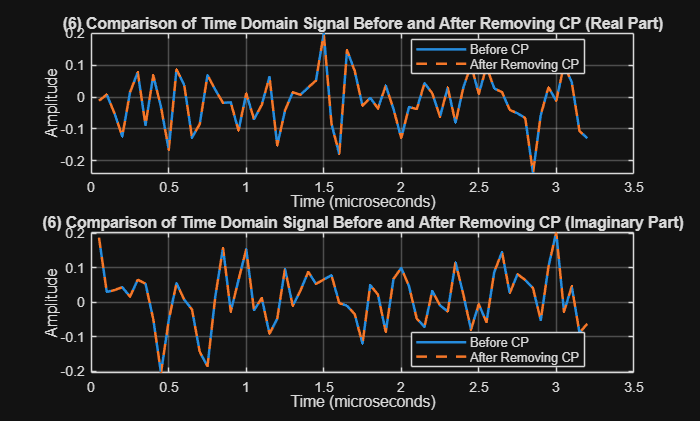

% Remove cyclic prefix from the OFDM signal
noiseless_ofdm_without_cp = ofdm_with_cp(cp_size+1:end); % Remove the cyclic prefix

% Plot the time domain signal before and after removing the cyclic prefix
figure;

% Plot the real part of the time domain signal before and after removing CP
subplot(2, 1, 1);
plot(sampled_time, real(ofdm_symbol_ifft), 'LineWidth', 1.5); 
hold on;
plot(sampled_time, real(noiseless_ofdm_without_cp), '--', 'LineWidth', 1.5);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('(6) Comparison of Time Domain Signal Before and After Removing CP (Real Part)');
legend('Before CP', 'After Removing CP', 'Location', 'Best');
grid on;
hold off;

% Plot the imaginary part of the time domain signal before and after removing CP
subplot(2, 1, 2);
plot(sampled_time, imag(ofdm_symbol_ifft), 'LineWidth', 1.5); 
hold on;
plot(sampled_time, imag(noiseless_ofdm_without_cp), '--', 'LineWidth', 1.5);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('(6) Comparison of Time Domain Signal Before and After Removing CP (Imaginary Part)');
legend('Before CP', 'After Removing CP', 'Location', 'Best');
grid on;
hold off;

(7) FFT the signal transmitted through ideal channel and plot the magnitude of both the recieved and transmitted spectrum with 0 in the middle

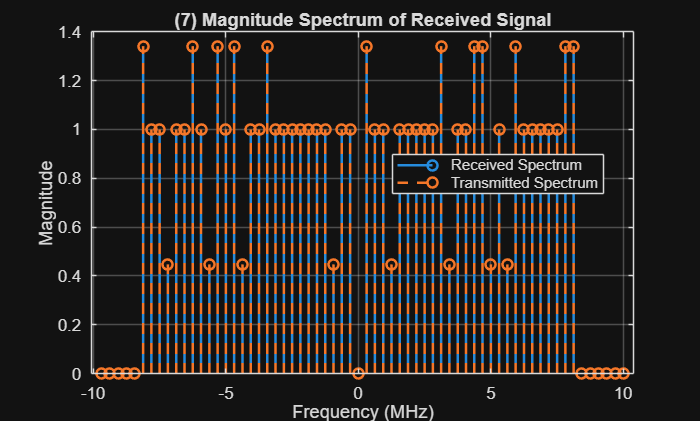

% FFT the signal transmitted through ideal channel
fft_no_cp = fftshift(fft(noiseless_ofdm_without_cp, fft_size));

% Compute the frequency axis for plotting
f_fft = subcarrier_spacing * (-(fft_size/2 - 1):(fft_size/2));

% Plot the magnitude of the FFT with 0 in the middle
figure;
stem(f_fft, abs(fft_no_cp), 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Magnitude');
title('(7) Magnitude Spectrum of Received Signal');
grid on;
% Overlay the original spectrum on the received signal spectrum
hold on;
stem(f_fft, abs(ofdm_symbol), 'LineWidth', 1.5, 'DisplayName', 'Original Spectrum', 'LineStyle', '--');
legend('Received Spectrum', 'Transmitted Spectrum', 'Location', 'Best');
hold off;

(8) Generate 1000 OFDM symbols. Peak Power? Average Power? PAPR?

num_symbols = 1000; % Number of OFDM symbols to generate
peak_power = zeros(num_symbols, 1); % Initialize array to store peak power
average_power = zeros(num_symbols, 1); % Initialize array to store average power
papr = zeros(num_symbols, 1); % Initialize array to store PAPR
ofdm_symbol_1000 = zeros(64, 1000);
ofdm_symbol_time_1000 = zeros(64, 1000);

for k = 1:num_symbols
    % Generate random bits for pilot and data tones
    pilot_tone_bits_element = randi([0 1], 4, 1) * 2 - 1; % Generate random bits and modulate with BPSK
    data_tone_bits_element = randi([0 15], fft_size - length(pilot_tone_idx) - length(null_carriers), 1); % Generate random bits for 16-QAM
    data_tone_modulated_element = qammod(data_tone_bits_element, 16, 'UnitAveragePower', true);
    
    % Create OFDM symbol
    ofdm_symbol_element = zeros(fft_size, 1); % Initialize OFDM symbol with zeros
    ofdm_symbol_element(pilot_tone_idx + idx_offset) = pilot_tone_bits_element; % Assign pilot tones
    data_indices_element = setdiff(1:fft_size, [null_carriers + idx_offset, pilot_tone_idx + idx_offset]); % Find indices for data tones
    ofdm_symbol_element(data_indices_element) = data_tone_modulated_element; % Allocate modulated data tones to remaining indices
    
    ofdm_symbol_1000(:, k) = ofdm_symbol_element;

    % Compute IFFT to get time domain signal
    ofdm_symbol_ifft = ifft(ifftshift(ofdm_symbol_element));
    
    ofdm_symbol_time_1000(:, k) = ofdm_symbol_ifft; % Store time domain signal for each symbol
    
    % Calculate peak and average power
    peak_power(k) = max(abs(ofdm_symbol_ifft))^2; % Peak power
    average_power(k) = mean(abs(ofdm_symbol_ifft).^2); % Average power
    
end

% Display results
disp(['Peak Power: ' num2str(max(peak_power))]);

Peak Power: 0.1659


disp(['Average Power: ' num2str(mean(average_power))]);

Average Power: 0.012658


disp(['PAPR: ' num2str(10 * log10(max(peak_power) / mean(average_power))) ' dB']);

PAPR: 11.175 dB


(9) Transmit the 1000 OFDM symbols with 15 dB SNR

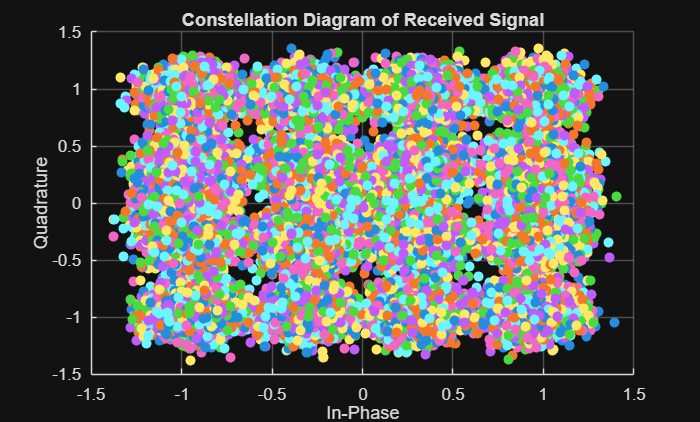

% Add cyclic prefix to each generated OFDM symbol
ofdm_time_with_cp_1000 = [ofdm_symbol_time_1000(end-cp_size+1:end, :); ofdm_symbol_time_1000]; 

% Add 15 dB AWGN to the signals with cyclic prefix
ofdm_time_with_cp_awgn_1000 = awgn(ofdm_time_with_cp_1000, 15, 'measured');

% Remove cyclic prefix at the receiver
noisy_ofdm_without_cp_1000 = ofdm_time_with_cp_awgn_1000(cp_size+1:end, :);

% Demodulate the received symbols
received_const = zeros(size(noisy_ofdm_without_cp_1000));
for k = 1:num_symbols
    % Perform FFT on the received signal
    received_symbol = fftshift(fft(noisy_ofdm_without_cp_1000(:, k)));
    
    % Demodulate the data tones
    % demodulated_data = qamdemod(received_symbol(data_indices_element), 16, 'UnitAveragePower', true);
    received_const(:, k) = received_symbol;
end

% Plot the constellation diagram for the last symbol
% Remove pilot tones from the received constellation
received_const_no_pilots = received_const;
received_const_no_pilots(pilot_tone_idx + idx_offset, :) = [];

figure;
scatter(real(received_const(:, :)), imag(received_const(:, :)), 'filled');
xlabel('In-Phase');
ylabel('Quadrature');
title('Constellation Diagram of Received Signal');
grid on;


% Calculate empirical SNR
signal_power = mean(abs(noisy_ofdm_without_cp_1000).^2, 1); % Signal power for each symbol
noise_power = mean(abs(ofdm_time_with_cp_1000(cp_size+1:end, :) - ofdm_time_with_cp_awgn_1000(cp_size+1:end, :)).^2, 1); % Noise power for each symbol
empirical_snr = mean(10 * log10(signal_power ./ noise_power)); % Calculate SNR in dB

% Display empirical SNR results
disp(['Empirical SNR: ' num2str(empirical_snr') ' dB. This is close to 15 dB']);

Empirical SNR: 15.1686 dB. This is close to 15 dB


(11) Transmit and receive 1000 different OFDM symbols with SNR = {0 dB, 5 dB, 10 dB, 15 dB} and plot BER vs SNR relation and give a brief description.

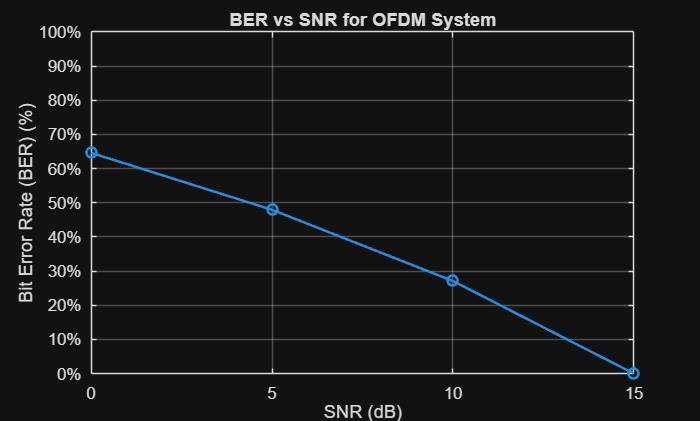

snr_values = [0, 5, 10, 15]; % SNR values in dB
num_snr_values = length(snr_values);
ber = zeros(num_snr_values, 1); % Initialize BER array

for snr_idx = 1:num_snr_values
    % Add AWGN to the signals with cyclic prefix for current SNR
    ofdm_time_with_cp_awgn_element = awgn(ofdm_time_with_cp_1000, snr_values(snr_idx), 'measured');
    
    % Remove cyclic prefix at the receiver
    noisy_ofdm_without_cp_element = ofdm_time_with_cp_awgn_element(cp_size+1:end, :);
    
    % Demodulate the received symbols
    received_const = zeros(size(noisy_ofdm_without_cp_element));
    for k = 1:num_symbols
        % Perform FFT on the received signal
        received_symbol = fftshift(fft(noisy_ofdm_without_cp_element(:, k)));
        
        % Demodulate the data tones
        demodulated_data = qamdemod(received_symbol(data_indices_element), 16, 'UnitAveragePower', true);
        received_const(:, k) = received_symbol;
    end
    
    % Calculate the number of errors for BER
    errors = 0;
    for k = 1:num_symbols
        % Compare the transmitted and received data
        transmitted_data = data_tone_bits_element; % Original transmitted data
        received_data = demodulated_data; % Received data after demodulation
        errors = errors + sum(transmitted_data ~= received_data); % Count errors
    end
    
    % Calculate BER
    ber(snr_idx) = errors / (num_symbols * (fft_size - length(pilot_tone_idx) - length(null_carriers)));
end

% Plot BER vs SNR
figure;
plot(snr_values, ber, '-o', 'LineWidth', 1.5);
ylabel('Bit Error Rate (BER) (%)');
xlabel('SNR (dB)');
yticks(0:0.1:1); % Set y-ticks from 0 to 1 in increments of 0.1
yticklabels(cellstr(num2str((0:0.1:1)' * 100, '%.0f%%'))); % Convert y-ticks to percentage format
title('BER vs SNR for OFDM System');
ylim([0 1]);
grid on;


% Brief description
disp('As SNR increases, the BER decreases, indicating better performance of the system under higher signal-to-noise conditions.');

As SNR increases, the BER decreases, indicating better performance of the system under higher signal-to-noise conditions.


## Part 2

(1) Generate STS symbols

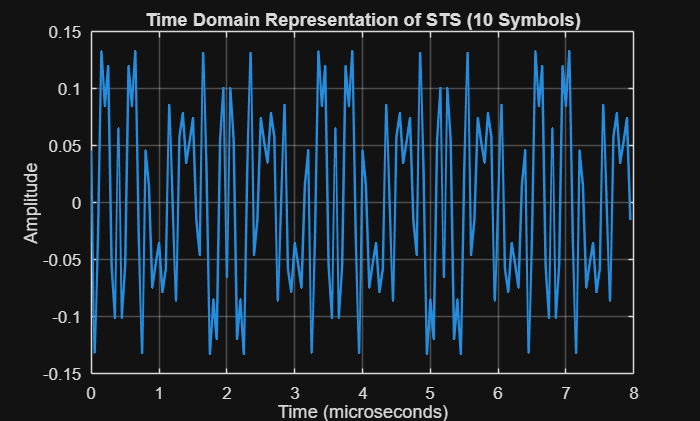

sts = sqrt(13 / 6) * [0 0 0 0 0 ...
0 0 1+1j 0 0 0 -1-1j 0 0 0 1+1j 0 0 0 -1-1j 0 0 0 -1-1j 0 0 0 1+1j 0 0 0 0 0 0 0 -1-1j 0 0 0 -1-1j 0 0 0 1+1j 0 0 0 1+1j 0 0 0 1+1j 0 0 0 1+1j 0 0 ...
0 0 0 0 0 0].';

sts_time = ifft(ifftshift(sts));
% Concatenate sts_time to create 10 symbol training sequence
sts_time_10_symbols = [sts_time; sts_time; sts_time(1:floor(end/2))];

sts_time_steps = (1 / fs * 1e6) * (0:length(sts_time_10_symbols) - 1); % Time vector for the duration of the signal

figure;
plot(sts_time_steps, real(sts_time_10_symbols), 'LineWidth', 1.5); % Plot real part of the training sequence
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('Time Domain Representation of STS (10 Symbols)');
grid on;

(2) Generate LTS Symbols

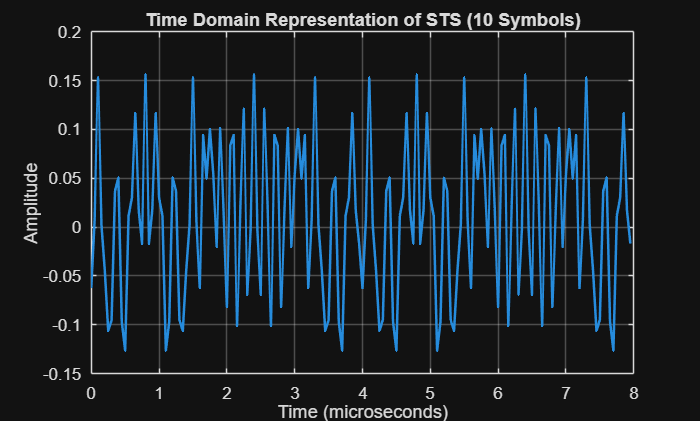

lts = [0 0 0 0 0 ...
    1 1 -1 -1 1 1 -1 1 -1 1 1 1 1 1 1 -1 -1 1 1 -1 1 -1 1 1 1 1 0 1 -1 -1 1 1 -1 1 -1 1 -1 -1 -1 -1 -1 1 1 -1 -1 1 -1 1 -1 1 1 1 1 ...
    0 0 0 0 0 0].';

lts_time = ifft(ifftshift(lts)); % Convert LTS to time domain
lts_time_with_cp = [lts_time((end-cp_size+1):end); lts_time]; % Add cyclic prefix to LTS
lts_time_with_cp_2point5 = [lts_time_with_cp; lts_time_with_cp];

lts_time_steps = (1 / fs * 1e6) * (0:length(lts_time_with_cp_2point5) - 1); % Time vector for the duration of the signal

figure;
plot(lts_time_steps, real(lts_time_with_cp_2point5), 'LineWidth', 1.5); % Plot real part of the training sequence
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('Time Domain Representation of STS (10 Symbols)');
grid on;

(3) Create a frame with STS-LTS-OFDM Symbols x5

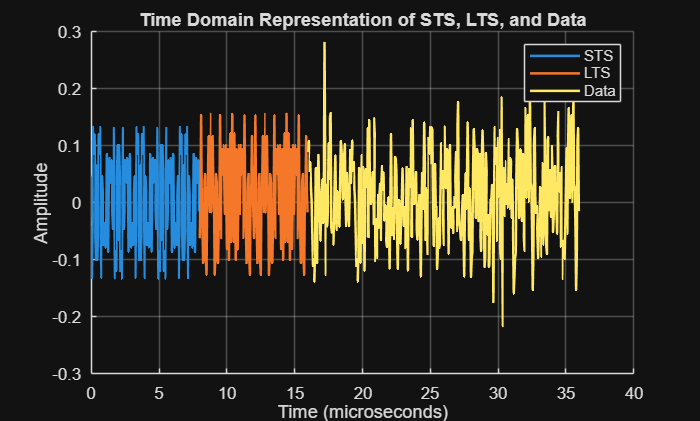

num_symbols = 5; % Set the number of OFDM symbols to generate
ofdm_symbol_element = zeros(fft_size, num_symbols); % Preallocate array for OFDM symbols
tx_symbols = zeros(fft_size - length(pilot_tone_idx) - length(null_carriers), num_symbols);

for k = 1:num_symbols
    % Generate random data for modulation
    data_bits_element = randi([0 15], fft_size - length(pilot_tone_idx) - length(null_carriers), 1); % Random data
    data_tone_modulated_element = qammod(data_bits_element, 16, 'UnitAveragePower', true); % QAM modulation
    tx_symbols(:, k) = data_bits_element;
    pilot_tone_idx_element = [-21, -7, 7, 21];
    pilot_tone_bits_element = randi([0 1], 4, 1) * 2 - 1; % Generate random bits and modulate with BPSK

    % Find indices for data tones
    data_indices_element = setdiff(1:fft_size, [null_carriers + idx_offset, pilot_tone_idx_element + idx_offset]); % Find indices for data tones
    ofdm_symbol_element(data_indices_element, k) = data_tone_modulated_element; % Allocate modulated data tones to remaining indices
    ofdm_symbol_element(pilot_tone_idx_element + idx_offset, k) = pilot_tone_bits_element; % Assign pilot tones
end

% Perform IFFT on the OFDM symbols after applying FFT shift
ofdm_time_with_cp_element = ifft(ifftshift(ofdm_symbol_element, 1), [], 1);

% Add cyclic prefix to the time domain signal
ofdm_time_with_cp_element = [ofdm_time_with_cp_element(end-cp_size+1:end, :); ofdm_time_with_cp_element];

% Create an OFDM frame with STS-LTS-5 OFDM symbols
% Create the OFDM frame components separately
% Normalize each frame so that all of them have the same energy
% sts_frame = sts_time_10_symbols / norm(sts_time_10_symbols); % STS portion
sts_frame = sts_time_10_symbols;
% lts_frame = lts_time_with_cp_2point5 / norm(lts_time_with_cp_2point5); % LTS portion
lts_frame = lts_time_with_cp_2point5;
data_frame = reshape(ofdm_time_with_cp_element, [], 1); % Data portion
% data_frame = data_frame / norm(data_frame); % Normalize data portion

% Concatenate time vectors for each portion
total_time_steps = (1 / fs * 1e6) * (0:(length(sts_frame) + length(lts_frame) + length(data_frame) - 1));

% Create concatenated signal
concatenated_signal = [sts_frame; lts_frame; data_frame];

figure;
% Plot concatenated signal
% plot(total_time_steps, real(concatenated_signal), 'LineWidth', 1.5);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('Time Domain Representation of STS, LTS, and Data');
grid on;

% Add legend to differentiate between STS, LTS, and Data
hold on;
plot((1 / fs * 1e6) * (0:length(sts_frame) - 1), real(sts_frame), 'LineWidth', 1.5, 'DisplayName', 'STS');
plot((1 / fs * 1e6) * (length(sts_frame):(length(sts_frame) + length(lts_frame) - 1)), real(lts_frame), 'LineWidth', 1.5, 'DisplayName', 'LTS');
plot((1 / fs * 1e6) * (length(sts_frame) + length(lts_frame):(length(sts_frame) + length(lts_frame) + length(data_frame) - 1)), real(data_frame), 'LineWidth', 1.5, 'DisplayName', 'Data');
hold off;
legend('show');

(4) Create a matched filter to detect STS

✅ First STS detected at sample index: 1


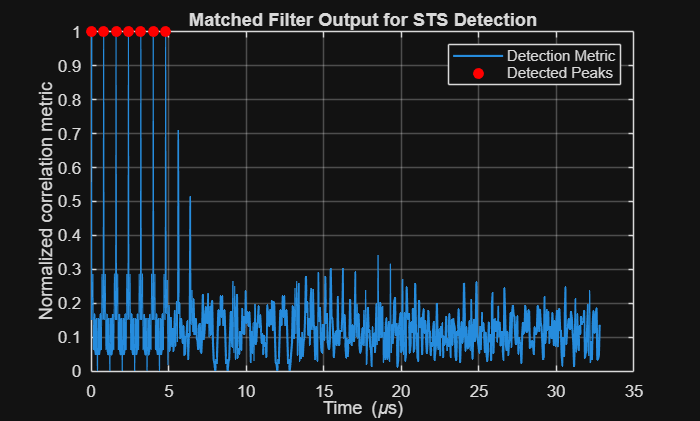

%% (4) --- STS Detection using Matched Filter ---
% Known short symbol (one 16-sample STS repetition)

function [sts_start, sts_finish] = locate_sts(sig, sts_time_10_symbols, fs, channel)

L = length(sts_time_10_symbols);

r = sig;
mf_output = conv(r, flipud(conj(sts_time_10_symbols)), 'valid');
% energy_window = movsum(abs(r).^2, [L-1 0]);
% 
% eps_val = 1e-9;
% metric = abs(mf_output).^2 ./ (energy_window(L:end) + eps_val);

% metric = metric / max(metric);
mf_output = mf_output / max(mf_output);
threshold = 0.8; % adjust based on SNR
[peaks, locs] = findpeaks([0; abs(mf_output)], 'MinPeakHeight', threshold);
locs = locs - 1;

if isempty(locs)
    disp('⚠️ No STS detected. Try lowering threshold.');
else
    if strcmpi(channel, 'noisy')
        [~, best_loc] = max(peaks);
        sts_start = locs(best_loc);
    else
        sts_start = locs(1);
    end
    sts_finish = locs(end) + L - 1; % Calculate the finish index of the STS
    fprintf('✅ First STS detected at sample index: %d\n', sts_start);
    % fprintf('✅ Last STS finishes at sample index: %d\n', sts_finish);
end

t_axis = (1/fs * 1e6) * (0:length(mf_output)-1);

figure;
plot(t_axis, abs(mf_output), 'LineWidth', 1.3);
xlabel('Time (\mus)');
ylabel('Normalized correlation metric');
title('Matched Filter Output for STS Detection');
grid on;
hold on;

if ~isempty(locs)
    plot(t_axis(locs), abs(mf_output(locs)), 'ro', 'MarkerFaceColor', 'r');
    legend('Detection Metric', 'Detected Peaks');
end
hold off;
end

locate_sts(concatenated_signal, sts_time, fs, 'clean');

disp(['(4) The algorithm detects the start of the OFDM frame by cross-correlating the received signal with the known short training symbol,']);

(4) The algorithm detects the start of the OFDM frame by cross-correlating the received signal with the known short training symbol,


disp(['normalizing by local energy, and identifying the peak in the resulting correlation metric as the STS location.']);

normalizing by local energy, and identifying the peak in the resulting correlation metric as the STS location.


(5) Algorithm Verification

✅ First STS detected at sample index: 31


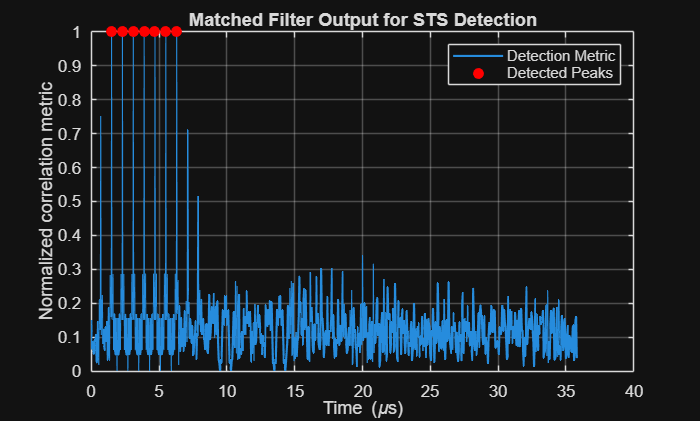

zeropads = zeros(30, 1);
padded_concatenated_signal = [zeropads; concatenated_signal; zeropads];

padded_t = (0:length(padded_concatenated_signal) - 1) * 1 / fs * 1e6;

[sts_start, sts_finish] = locate_sts(padded_concatenated_signal, sts_time, fs, 'clean');


disp('Yes, it identifies the beginning of the frame.');

Yes, it identifies the beginning of the frame.


% Identify the start of each data symbol based on STS identification results
data_symbol_length = size(ofdm_time_with_cp_element, 1); % Length of each data symbol
num_data_symbols = size(ofdm_time_with_cp_element, 2); % Total number of data symbols

% Calculate the start indices for each data symbol
% data_symbol_starts = sts_start + (0:num_data_symbols-1) * data_symbol_length;
data_symbol_starts = sts_start + 320 + (0:num_data_symbols-1) * data_symbol_length; % b/c 12.5 preamble symbols, 4 bits per symbol, and 0.05 us per bit
disp(['The data symbols starts at ' num2str(data_symbol_starts)]);

The data symbols starts at 351  431  511  591  671


(6) Process the identified data symbols

% Remove cyclic prefix from each data symbol
demodulated_symbols = zeros(fft_size, num_data_symbols);
for k = 1:num_data_symbols
    % Extract the symbol without the cyclic prefix
    symbol_start = data_symbol_starts(k);
    demodulated_symbols(:, k) = padded_concatenated_signal(symbol_start + (cp_size:(data_symbol_length - 1)), 1);
end

% demodulated_symbols = reshape(padded_concatenated_signal(351:(end-30)), [], 5);
% demodulated_symbols = demodulated_symbols((cp_size + 1): end, :);


demodulated_symbols_fft = fftshift(fft(demodulated_symbols, [], 1), 1);

% Compare with originally coded data symbols
comparison_result = all(demodulated_symbols_fft - ofdm_symbol_element < 1e-5, 'all');

if comparison_result
    disp('✅ Demodulated data matches the originally coded data symbols.');
else
    disp('⚠️ There is a difference between demodulated data and originally coded data symbols.');
end

✅ Demodulated data matches the originally coded data symbols.


(7) Verify the algorithm under 0 dB SNR noisy channel condition

✅ First STS detected at sample index: 31


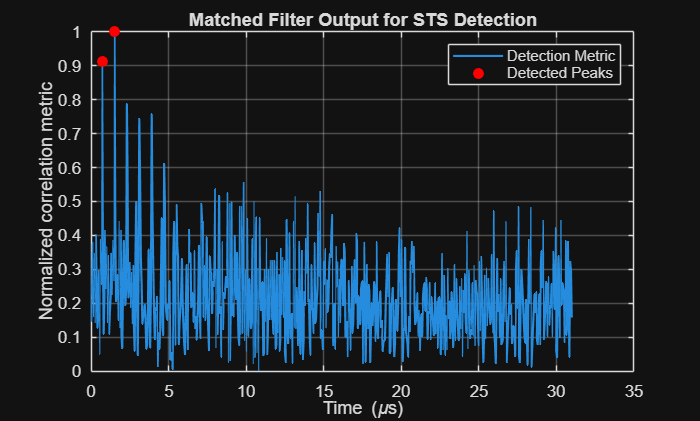

noisy_padded_concatenated_signal = awgn(padded_concatenated_signal, 10);

[noisy_sts_start, noisy_sts_finish] = locate_sts(noisy_padded_concatenated_signal, sts_time_10_symbols, fs, 'noisy');

disp(['Yes, it can identify the start of each frame. However, it sometimes fails to identify correctly due to the high noise.']);

Yes, it can identify the start of each frame. However, it sometimes fails to identify correctly due to the high noise.


(8) Create another match filter for LTS

✅ First LTS detected at sample index: 191


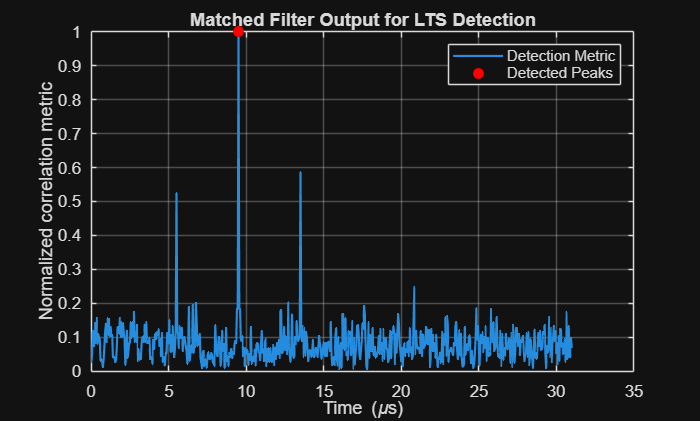

%% LTS Detection using Matched Filter ---
function [sts_start, sts_finish] = locate_lts(sig, lts_time_with_cp_2point5, fs, channel)

L = length(lts_time_with_cp_2point5);

r = sig;
mf_output = conv(r, flipud(conj(lts_time_with_cp_2point5)), 'valid');
% energy_window = movsum(abs(r).^2, [L-1 0]);
% 
% eps_val = 1e-9;
% metric = abs(mf_output).^2 ./ (energy_window(L:end) + eps_val);

% metric = metric / max(metric);
mf_output = mf_output / max(mf_output);
threshold = 0.8; % adjust based on SNR
[peaks, locs] = findpeaks([0; abs(mf_output)], 'MinPeakHeight', threshold);
locs = locs - 1;

if isempty(locs)
    disp('⚠️ No LTS detected. Try lowering threshold.');
else
    if strcmpi(channel, 'noisy')
        [~, best_loc] = max(peaks);
        sts_start = locs(best_loc);
    else
        sts_start = locs(1);
    end
    sts_finish = locs(end) + L - 1; % Calculate the finish index of the STS
    fprintf('✅ First LTS detected at sample index: %d\n', sts_start);
    % fprintf('✅ Last STS finishes at sample index: %d\n', sts_finish);
end

t_axis = (1/fs * 1e6) * (0:length(mf_output)-1);

figure;
plot(t_axis, abs(mf_output), 'LineWidth', 1.3);
xlabel('Time (\mus)');
ylabel('Normalized correlation metric');
title('Matched Filter Output for LTS Detection');
grid on;
hold on;

if ~isempty(locs)
    plot(t_axis(locs), abs(mf_output(locs)), 'ro', 'MarkerFaceColor', 'r');
    legend('Detection Metric', 'Detected Peaks');
end
hold off;
end

% Call the LTS detection function
lts_start = locate_lts(padded_concatenated_signal, lts_time_with_cp_2point5, fs, 'clean');

disp(['The algorithm detects the start of the LTS by identifying the index of maximum normalized ']);

The algorithm detects the start of the LTS by identifying the index of maximum normalized 


disp(['cross-correlating the received signal with the known long training symbol.']);

cross-correlating the received signal with the known long training symbol.


(9) Identify LTS under 0 dB SNR channel

✅ First LTS detected at sample index: 191


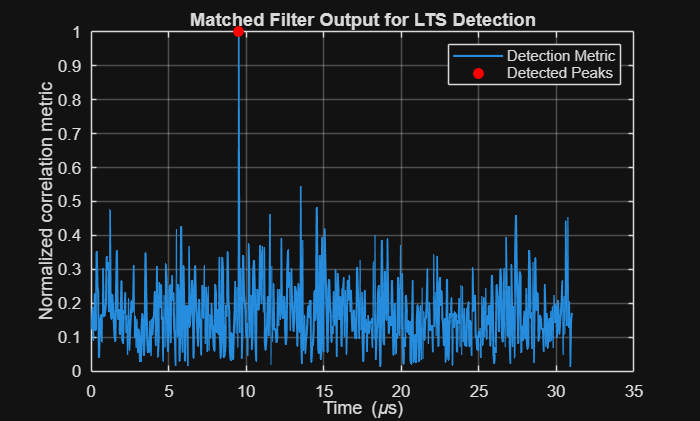

noisy_lts_start = locate_lts(noisy_padded_concatenated_signal, lts_time_with_cp_2point5, fs, 'noisy');

disp(['It can clearly identify the start of the first LTS']);

It can clearly identify the start of the first LTS


(10) Compare STS detection and LTS detection

disp('LTS identification is more robust to noise.');

LTS identification is more robust to noise.


(11)  plot LoS, NLoS, and summed signal in one figure

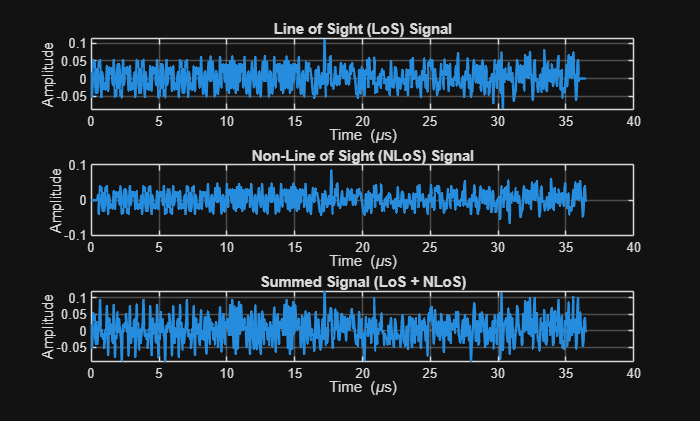

att_LoS = 0.4;
att_NLoS = 0.3;
LoS = concatenated_signal * att_LoS;
delay = 0.5;
NLoS = [zeros(delay / (1/fs * 1e6), 1); concatenated_signal] * att_NLoS;
N = max(length(LoS), length(NLoS));

LoS = [LoS; zeros(N - length(LoS), 1);];
NLoS = [zeros(N - length(NLoS), 1); NLoS];

summed_sig = LoS + NLoS;

% Plot the three signals in subplots
figure;

subplot(3, 1, 1);
plot((1 / fs * 1e6) * (0:length(LoS) - 1), real(LoS), 'LineWidth', 1.5);
xlabel('Time (\mus)');
ylabel('Amplitude');
title('Line of Sight (LoS) Signal');
grid on;

subplot(3, 1, 2);
plot((1 / fs * 1e6) * (0:length(NLoS) - 1), real(NLoS), 'LineWidth', 1.5);
xlabel('Time (\mus)');
ylabel('Amplitude');
title('Non-Line of Sight (NLoS) Signal');
grid on;

subplot(3, 1, 3);
plot((1 / fs * 1e6) * (0:length(summed_sig) - 1), real(summed_sig), 'LineWidth', 1.5);
xlabel('Time (\mus)');
ylabel('Amplitude');
title('Summed Signal (LoS + NLoS)');
grid on;

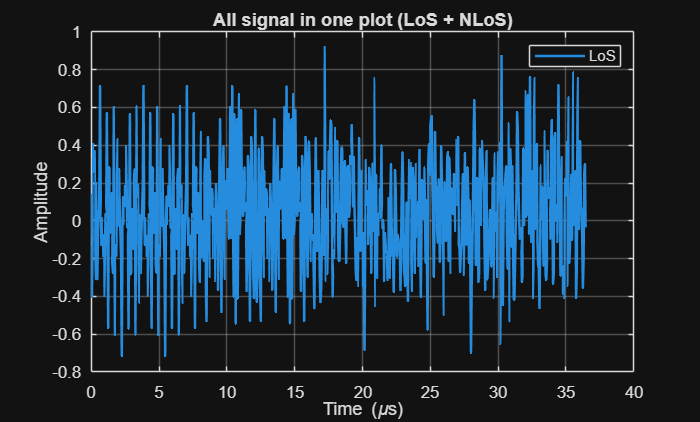


figure;
% plot((1 / fs * 1e6) * (0:length(LoS) - 1), real(LoS)/max(abs(summed_sig)), 'LineWidth', 1.5);
% hold on;
% plot((1 / fs * 1e6) * (0:length(NLoS) - 1), real(NLoS)/max(abs(summed_sig)), 'LineWidth', 1.5);
plot((1 / fs * 1e6) * (0:length(summed_sig) - 1), real(summed_sig)/max(abs(summed_sig)), 'LineWidth', 1.5);
xlabel('Time (\mus)');
ylabel('Amplitude');
title('All signal in one plot (LoS + NLoS)');
grid on;
legend("LoS", "NLoS", "Summed Signal");

(12) Consdier a reciever not perfectly time synchronized, which starts sampling at t=0.2 microseconds

samp_delay = 0.2;
imperfect_sampling = summed_sig((int16(samp_delay / (1 / fs * 1e6)) + 1):end);

figure;
plot(0:(1 / fs * 1e6):(1.6 + samp_delay - (1 / fs * 1e6)), [0; 0; 0; 0; imperfect_sampling(1:32)]);

hold on;
plot(0:(1 / fs * 1e6):(1.6 + samp_delay - (1 / fs * 1e6)), LoS(1:36), '--');

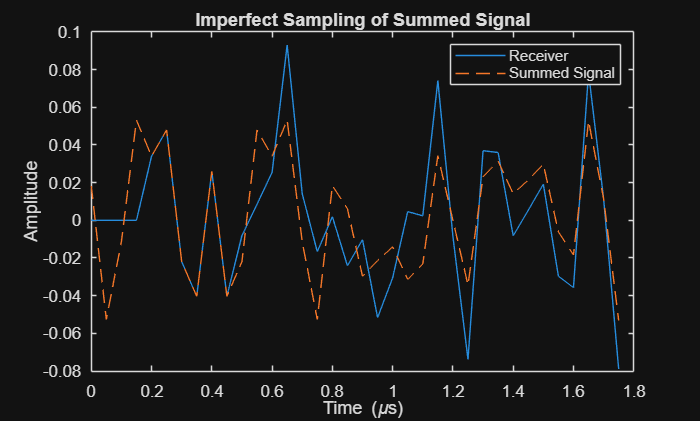

title('Imperfect Sampling of Summed Signal');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend('Receiver', 'Summed Signal');

disp('It can be seen that receiver does not capture any signal until t = 0.2 microseconds does it then overlap with the waveform of the summed signal.');

It can be seen that receiver does not capture any signal until t = 0.2 microseconds does it then overlap with the waveform of the summed signal.


disp('Showing that the imperfect synchronization is correctly implemented');

Showing that the imperfect synchronization is correctly implemented


(13) Apply LTS detection to the imperfectly sampled signal.

✅ First LTS detected at sample index: 157


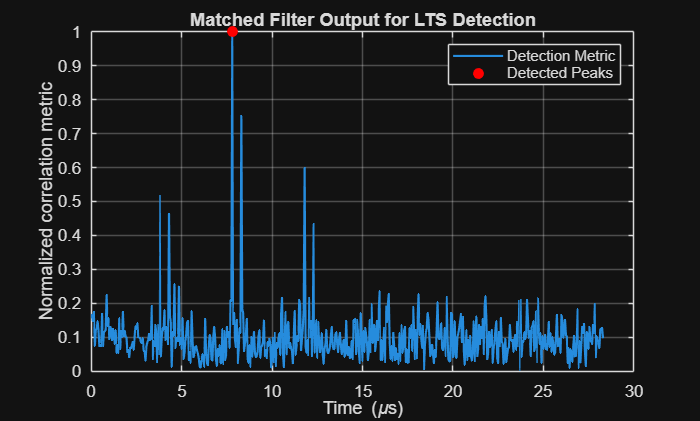

[imperfect_lts_start, imperfect_lts_finish] = locate_lts(imperfect_sampling, lts_time_with_cp_2point5, fs, 'clean');


theoretical_sts_duration = length(sts_time_10_symbols) / fs * 1e6; % in microseconds
actual_sts_duration = (imperfect_lts_start - 1) / fs * 1e6; % in microseconds


imperfect_sts_start = 0;
if actual_sts_duration <= theoretical_sts_duration
    imperfect_sts_start = 1
    imperfect_sts = imperfect_sampling(1:imperfect_lts_start - 1);
else
    imperfect_sts_start = imperfect_lts_start - 160;
    imperfect_sts = imperfect_sampling(imperfect_sts_start:(imperfect_lts_start-1));
end

imperfect_sts_start = 1

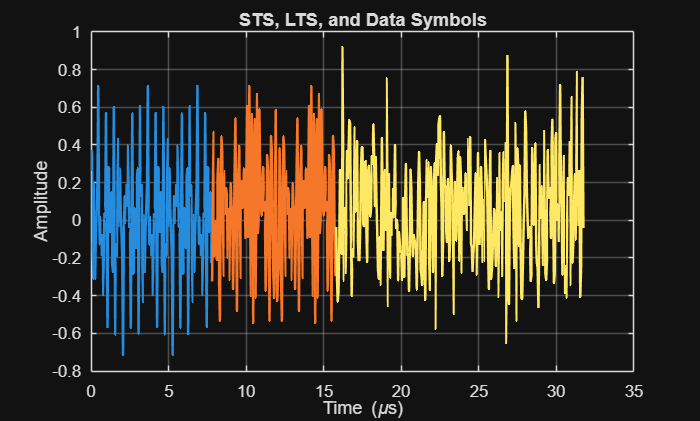


imperfect_lts = imperfect_sampling(imperfect_lts_start:(imperfect_lts_start + 159));    % LTS is 8us i.e. 160 indices long

% Calculate the start indices for each data symbol based on the imperfect LTS
imperfect_data_symbol_starts = imperfect_lts_start + 160 + (0:num_data_symbols-1) * data_symbol_length;

% Extract data symbols from the imperfectly sampled signal
imperfect_demodulated_symbols = zeros(fft_size, num_data_symbols);
for k = 1:num_data_symbols
    symbol_start = imperfect_data_symbol_starts(k);
    imperfect_demodulated_symbols(:, k) = imperfect_sampling(symbol_start + (cp_size:(data_symbol_length - 1)));
end

figure;

% Plot STS
plot((1 / fs * 1e6) * (0:length(imperfect_sts) - 1), real(imperfect_sts)/max(abs(imperfect_sampling)), 'LineWidth', 1.5);
hold on;

% Plot LTS
plot((1 / fs * 1e6) * (length(imperfect_sts):(length(imperfect_sts) + (length(imperfect_lts) - 1))), real(imperfect_lts)/max(abs(imperfect_sampling)), 'LineWidth', 1.5);

% Plot Data Symbols
data_symbol = zeros(fft_size, num_data_symbols);
% for k = 1:num_data_symbols
%     symbol_start = imperfect_data_symbol_starts(k);
%     data_symbol(:, k) = imperfect_sampling(symbol_start + (cp_size:(data_symbol_length - 1)));
% end

% data_symbol = reshape(data_symbol, [], 1);
data_symbol = reshape(imperfect_demodulated_symbols, [], 1);


plot((1 / fs * 1e6) * ((length(imperfect_sts) + length(imperfect_lts)):(length(imperfect_sts) + length(imperfect_lts) + length(data_symbol) - 1)), real(data_symbol)/max(abs(imperfect_sampling)), 'LineWidth', 1.5);
xlabel('Time (\mus)');
ylabel('Amplitude');
title('STS, LTS, and Data Symbols');
grid on;
hold off;

(14) Estimate the channel using LTS samples. Plot the estimated channel for both magnitude and phase.

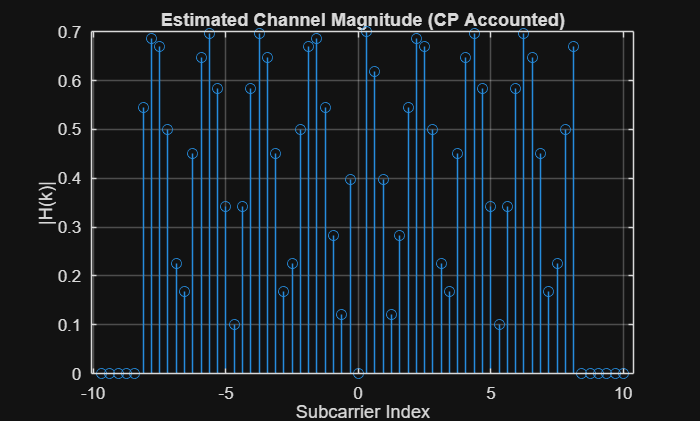

% Parameters
N = 64;  % subcarriers
cp_len = fft_size / 4;  % CP per LTS

% Split ideal and received LTS (each includes CP)
lts_tx_1 = lts_time_with_cp_2point5(1 : N + cp_len);
lts_tx_2 = lts_time_with_cp_2point5(N + cp_len + 1 : end);
lts_rx_1 = imperfect_lts(1 : N + cp_len);
lts_rx_2 = imperfect_lts(N + cp_len + 1 : end);

% To account for CP, do FFT over the *entire* symbol including CP
% The FFT length stays N, but we keep CP samples as part of the effective window
LTS_TX_1 = fftshift(fft(lts_tx_1(end-N+1:end), N));
LTS_TX_2 = fftshift(fft(lts_tx_2(end-N+1:end), N));
LTS_RX_1 = fftshift(fft(lts_rx_1(end-N+1:end), N));
LTS_RX_2 = fftshift(fft(lts_rx_2(end-N+1:end), N));

% Average the two received/transmitted FFTs
LTS_TX_avg = (LTS_TX_1 + LTS_TX_2) / 2;
LTS_RX_avg = (LTS_RX_1 + LTS_RX_2) / 2;

% Channel estimation (includes CP effect implicitly)
H_est = LTS_RX_avg ./ LTS_TX_avg;
H_est(null_carriers + idx_offset) = 0;
% Plot magnitude and phase
figure;
stem(f, abs(H_est));
title('Estimated Channel Magnitude (CP Accounted)');
xlabel('Subcarrier Index');
ylabel('|H(k)|');
grid on;

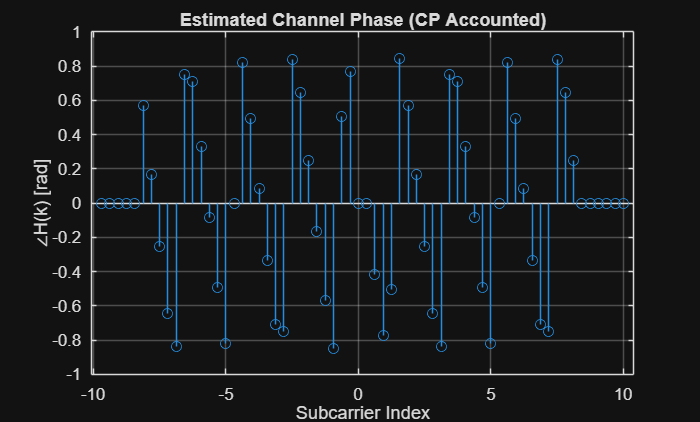


figure;
stem(f, angle(H_est));
title('Estimated Channel Phase (CP Accounted)');
xlabel('Subcarrier Index');
ylabel('∠H(k) [rad]');
grid on;

(15) Describe the estimated channel

disp(['An attenuation can be observed through the channel due to the given channel attenuation characteristic. Also, the']);

An attenuation can be observed through the channel due to the given channel attenuation characteristic. Also, the


disp(['phase change through the channel is periodic for every 6 sub carriers, this is mainly caused by the NLoS delay.']);

phase change through the channel is periodic for every 6 sub carriers, this is mainly caused by the NLoS delay.


(16) Equalize the imperfectly sampled OFDM symbols with the estimated channel.

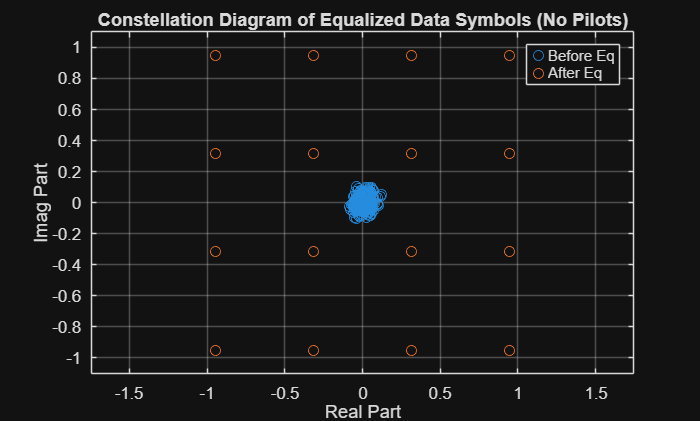

% Define subcarrier indices (after fftshift)
N = fft_size;
subcarrier_indices = (-N/2 + 1 : N/2);

% Define pilot and null subcarriers (802.11a standard)
pilot_indices = [-21 -7 7 21];
null_indices = [0];  % DC carrier
excluded_indices = [pilot_indices null_carriers];

% Find the logical mask for data subcarriers
data_mask = ~ismember(subcarrier_indices, excluded_indices);

% Equalize data symbols
equalized_data_symbols = zeros(size(imperfect_demodulated_symbols));
data_symbol = reshape(data_symbol, fft_size, []);
for k = 1:num_data_symbols
    equalized_data_symbols(:, k) = fftshift(fft(data_symbol(:, k))) ./ H_est;
end

% Keep only data subcarriers
equalized_data_only = equalized_data_symbols(data_mask, :);

% Plot the constellation (data subcarriers only)
figure;
plot(real(data_symbol(:)), imag(data_symbol(:)), 'o');
hold on;

plot(real(equalized_data_only(:)), imag(equalized_data_only(:)), 'o');
xlabel('Real Part');
ylabel('Imag Part');
title('Constellation Diagram of Equalized Data Symbols (No Pilots)');
grid on;
xlim([-1.1 1.1]);
ylim([-1.1 1.1]);
axis equal;
legend("Before Eq", "After Eq");
hold off;

% Demodulate the symbols using QAM
M = 16; % Modulation order for 16-QAM 
demodulated_symbols = qamdemod(equalized_data_only, M, 'UnitAveragePower', true);

% Compare with the transmitted data indices
BER = sum(demodulated_symbols(:) ~= tx_symbols(:)) / length(reshape(tx_symbols, 1, []));

% Display the Bit Error Rate (BER)
disp(['Bit Error Rate (BER): ', num2str(BER)]);

Bit Error Rate (BER): 0
